# **PESTools - Example 005 - Showcase of the available PES background curves that can be used for fitting**

## Author : PCC

This example shows all of the curve line-shapes that are available to use when fitting to either ARPES or XPS data obtained from the ADRESS beamline. 

- **For Backgrounds:** **Linear**, **Shirley** and **Offset Shirley** functions are available

close all; clear all;
pp = plot_props();

# **The function used to create the best-fit background curves to PES data**

% First create an artificial PES spectrum, whose background will be determined
zdat     = [];
% (A) - Defining the input parameters
TYPE    = "sGLA";   % type of curve to use for fitting. Default: "sGLA" ("pGLA", "DS")
BE      = -17.0;     % scalar of the binding energy of PE curve.
INT     = 1.0;      % scalar of the peak intensity of PE curve.
FWHM    =  0.1;     % scalar of the FWHM of the PE curve.
MR      =  0.5;     % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSE     = -1.0;     % scalar of the binding energy of spin-orbit split PE curve.
LSI     =  0.5;     % calar of the branching ratio of spin-orbit split PE curve.
LSW     =  0.0;     % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     =  0.2;     % scalar of the PE curve asymmetry parameter (usually for metallic systems).
% (B) - Calculating the lineshape
xdat    = linspace(BE-4, BE+4, 1e3);
zdat     = PESCurve(xdat, TYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY);
% -- Add artificial background and noise
zdat     = zdat - 0.01.*xdat' + 0.1;
zdat     = zdat .* (1 + 0.10*rand(length(zdat), 1));

The function 'PESBackground()' can be used to fit any background line-shape profile by defining the correct arguments to the function.

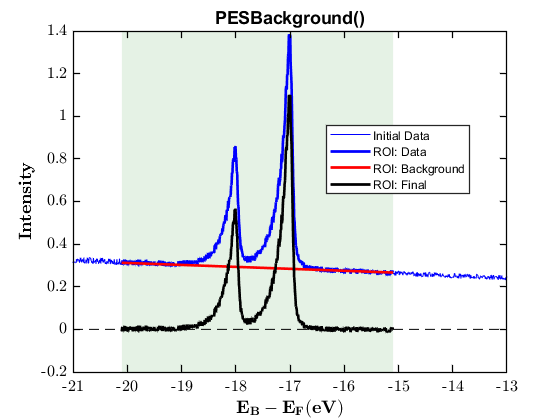

% 1 - Defining the input parameters
bTYPE   = "Poly";       % type of background to use for fitting. Default: "Poly" ("none", "Shir", "LinShir")
LHS     = -20.1;        % scalar of the START point on the LHS for background
RHS     = -15.1;        % scalar of the END point on the RHS for background
ORD     = 1;            % positive integer of the Polynomial Order for "Poly" background.
LAM     = 0.5;          % scalar for "LinShir" mixing ratio: lambda = 0 is Pure Shirley; lambda = 1 is Pure Linear.
DEL     = 0;            % scalar for the "LinShir" curve offset in binding energy.
BGR     = 0.00;         % scalar for a constant background to be included in the fit
% 2 - Determination of the background the lineshape
[roi_xdat, roi_int, roi_bgrnd] = PESBackground(xdat, zdat, bTYPE, LHS, RHS, ORD, LAM, DEL, BGR);
% 3 - Subtracting the background
roi_subtr_int     = roi_int - roi_bgrnd;
% 4 - Plotting the lineshape & background
figure(); hold on;
h = patch([LHS, LHS, RHS, RHS, LHS], [-1, 1, 1, -1, -1].*1e4, [0.8 0.9 0.8], 'facealpha', 0.5, 'edgecolor', 'none');
h.Annotation.LegendInformation.IconDisplayStyle = 'off';
plot(xdat, zdat, 'b-', 'linewidth', 0.5);
plot(roi_xdat, roi_int, 'b-', 'linewidth', 2);
plot(roi_xdat, roi_bgrnd, 'r-', 'linewidth', 2);
plot(roi_xdat, roi_subtr_int, 'k-', 'linewidth', 2);
gca_props(); title('PESBackground()'); 
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity $$', 'Interpreter', 'latex');
axis([-21, -13, -0.2, 1.4]);
legend({'Initial Data', 'ROI: Data', 'ROI: Background', 'ROI: Final'}, 'location', 'best', 'fontsize', 9);

# **Curves used for estimating the background**

## (1) Polynomial background

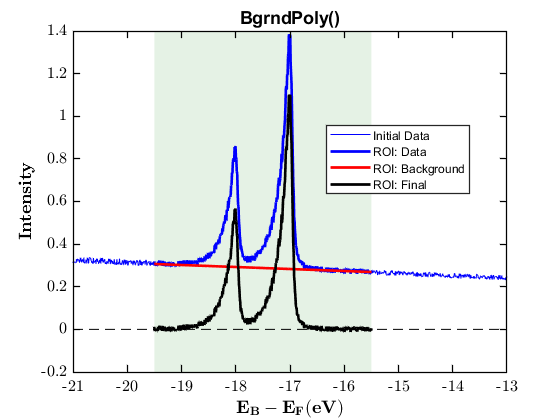

% 1 - Defining the input parameters
Order       = 1;                % positive integer of the Polynomial Order of background.
lhsLims     = BE-2.5;           % Start point of the LHS polynomial background (can also just be 1 value for the start)
rhsLims     = BE+1.5;           % Start point of the RHS polynomial background (can also just be 1 value for the end)
% 2 - Extracting best background
[roi_xdat, roi_int, roi_bgrnd] = BgrndPoly(xdat, zdat, lhsLims, rhsLims, Order);
% 3 - Subtracting the background
roi_subtr_int     = roi_int - roi_bgrnd;
% 4 - Plotting the lineshape & background
figure(); hold on;
h = patch([lhsLims, lhsLims, rhsLims, rhsLims, lhsLims], [-1, 1, 1, -1, -1].*1e4, [0.8 0.9 0.8], 'facealpha', 0.5, 'edgecolor', 'none');
h.Annotation.LegendInformation.IconDisplayStyle = 'off';
plot(xdat, zdat, 'b-', 'linewidth', 0.5);
plot(roi_xdat, roi_int, 'b-', 'linewidth', 2);
plot(roi_xdat, roi_bgrnd, 'r-', 'linewidth', 2);
plot(roi_xdat, roi_subtr_int, 'k-', 'linewidth', 2);
gca_props(); title('BgrndPoly()'); 
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity $$', 'Interpreter', 'latex');
axis([-21, -13, -0.2, 1.4]);
legend({'Initial Data', 'ROI: Data', 'ROI: Background', 'ROI: Final'}, 'location', 'best', 'fontsize', 9);

## (2) Shirley background

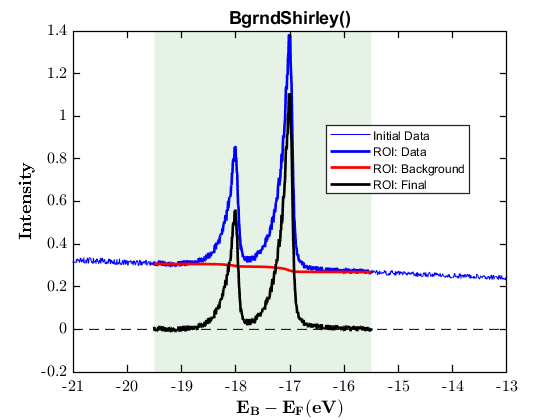

% 1 - Defining the input parameter
lhsLims     = BE-2.5;           % Start point of the LHS polynomial background (can also just be 1 value for the start)
rhsLims     = BE+1.5;           % Start point of the RHS polynomial background (can also just be 1 value for the end)
% 2 - Extracting best background
[roi_xdat, roi_int, roi_bgrnd] = BgrndShirley(xdat, zdat, lhsLims, rhsLims);
% 3 - Subtracting the background
roi_subtr_int     = roi_int - roi_bgrnd;
% 4 - Plotting the lineshape & background
figure(); hold on;
h = patch([lhsLims, lhsLims, rhsLims, rhsLims, lhsLims], [-1, 1, 1, -1, -1].*1e4, [0.8 0.9 0.8], 'facealpha', 0.5, 'edgecolor', 'none');
h.Annotation.LegendInformation.IconDisplayStyle = 'off';
plot(xdat, zdat, 'b-', 'linewidth', 0.5);
plot(roi_xdat, roi_int, 'b-', 'linewidth', 2);
plot(roi_xdat, roi_bgrnd, 'r-', 'linewidth', 2);
plot(roi_xdat, roi_subtr_int, 'k-', 'linewidth', 2);
gca_props(); title('BgrndShirley()'); 
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity $$', 'Interpreter', 'latex');
axis([-21, -13, -0.2, 1.4]);
legend({'Initial Data', 'ROI: Data', 'ROI: Background', 'ROI: Final'}, 'location', 'best', 'fontsize', 9);

## (3) Blended Shirley and Linear Backgrounds

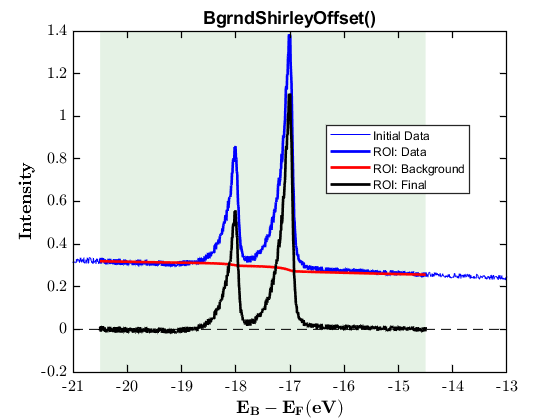

% 1 - Defining the input parameters
lhsLims     = BE-3.5;           % Start point of the LHS polynomial background (can also just be 1 value for the start)
rhsLims     = BE+2.5;           % Start point of the RHS polynomial background (can also just be 1 value for the end)
lambda      = 0.50;      % scalar for mixing ratio: lambda = 0 is Pure Shirley; lambda = 1 is Pure Linear.
delta       = 0.0;      % scalar for the Shirley curve offset in binding energy.
% 2 - Extracting best background
[roi_xdat, roi_int, roi_bgrnd] = BgrndShirleyOffset(xdat, zdat, lhsLims, rhsLims, lambda, delta);
% 3 - Subtracting the background
roi_subtr_int     = roi_int - roi_bgrnd;
% 4 - Plotting the lineshape & background
figure(); hold on;
h = patch([lhsLims, lhsLims, rhsLims, rhsLims, lhsLims], [-1, 1, 1, -1, -1].*1e4, [0.8 0.9 0.8], 'facealpha', 0.5, 'edgecolor', 'none');
h.Annotation.LegendInformation.IconDisplayStyle = 'off';
plot(xdat, zdat, 'b-', 'linewidth', 0.5);
plot(roi_xdat, roi_int, 'b-', 'linewidth', 2);
plot(roi_xdat, roi_bgrnd, 'r-', 'linewidth', 2);
plot(roi_xdat, roi_subtr_int, 'k-', 'linewidth', 2);
gca_props(); title('BgrndShirleyOffset()'); 
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity $$', 'Interpreter', 'latex');
axis([-21, -13, -0.2, 1.4]);
legend({'Initial Data', 'ROI: Data', 'ROI: Background', 'ROI: Final'}, 'location', 'best', 'fontsize', 9);

## (4) Fermi-Dirac Distribution (FDD) constant background

% 1 - Defining the input parameters
lhsLims     = BE-3.5;           % Start point of the LHS polynomial background (can also just be 1 value for the start)
rhsLims     = BE+2.5;           % Start point of the RHS polynomial background (can also just be 1 value for the end)
lambda      = 0.50;      % scalar for mixing ratio: lambda = 0 is Pure Shirley; lambda = 1 is Pure Linear.
delta       = 0.0;      % scalar for the Shirley curve offset in binding energy.
% 2 - Extracting best background
[roi_xdat, roi_int, roi_bgrnd] = BgrndShirleyOffset(xdat, zdat, lhsLims, rhsLims, lambda, delta);
% 3 - Subtracting the background
roi_subtr_int     = roi_int - roi_bgrnd;
% 4 - Plotting the lineshape & background
figure(); hold on;
h = patch([lhsLims, lhsLims, rhsLims, rhsLims, lhsLims], [-1, 1, 1, -1, -1].*1e4, [0.8 0.9 0.8], 'facealpha', 0.5, 'edgecolor', 'none');
h.Annotation.LegendInformation.IconDisplayStyle = 'off';
plot(xdat, zdat, 'b-', 'linewidth', 0.5);
plot(roi_xdat, roi_int, 'b-', 'linewidth', 2);
plot(roi_xdat, roi_bgrnd, 'r-', 'linewidth', 2);
plot(roi_xdat, roi_subtr_int, 'k-', 'linewidth', 2);
gca_props(); title('BgrndShirleyOffset()'); 
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity $$', 'Interpreter', 'latex');
axis([-21, -13, -0.2, 1.4]);
legend({'Initial Data', 'ROI: Data', 'ROI: Background', 'ROI: Final'}, 'location', 'best', 'fontsize', 9);